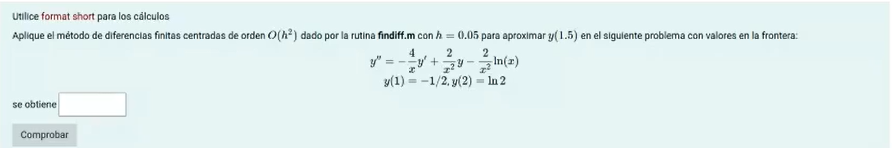

r= @(t) -(2*log(t))./(t.^2) % Solita

r = function_handle with value:
    @(t)-(2*log(t))./(t.^2)


q= @(t) 2./t.^2 % Acompaña a Y

q = function_handle with value:
    @(t)2./t.^2


p = @(t) -4./t % Acompaña a Y'

p = function_handle with value:
    @(t)-4./t


a=1

a = 1

b=2

b = 2

N = (b-a)/0.05 

N = 20

aplha= -0.5

aplha = -0.5000

beta = log(2)

beta = 0.6931

N = (b-a)/0.05

N = 20

F = findiff (p, q, r, a, b, -0.5, log(2), 20)

F =     1.0000   -0.5000
    1.0500   -0.3111
    1.1000   -0.1566
    1.1500   -0.0288
    1.2000    0.0780
    1.2500    0.1680
    1.3000    0.2445
    1.3500    0.3100
    1.4000    0.3665
    1.4500    0.4156



% En y(1.5) la aproximacion es 0.4584 Y MELA

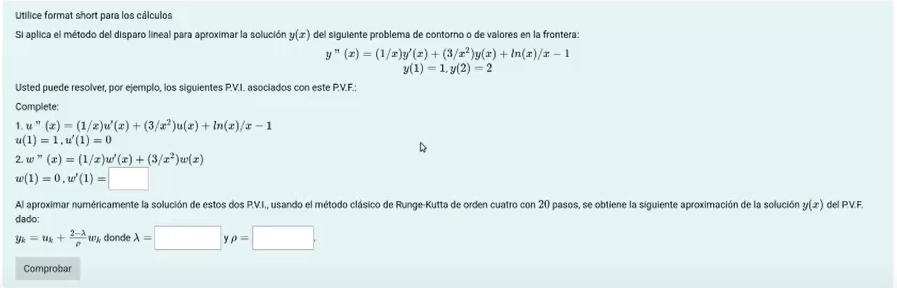

% Preguntan por w'(1)=1

% NOTA: Para los sistemas de disparo lineal, las condiciones iniciales son
% D1= alpha 0  ; D2 = 0 1

% EN este caso, w'(1)=1

% lambda debe ser el valor de u en el ultimo punto (ultimo punto es 2)

% ro debe de ser el valor de v eb el ultimo punto (2)

a=1

a = 1

b=2

b = 2

Se pide el valor de lamba que en este caso es U y de ro que en este caso es V

z1 = [1,0]

z1 =      1     0


z2 = [0,1]

z2 =      0     1


M = 20

M = 20

F1 = @(x,u) [u(2) , (1./x)*u(2)+(3./x.^2)*u(1)+(log(x)./x)-1]

F1 = function_handle with value:
    @(x,u)[u(2),(1./x)*u(2)+(3./x.^2)*u(1)+(log(x)./x)-1]


[T1, Z1] = rks4 (F1, a, b, z1, M)

T1 =     1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000


Z1 =     1.0000         0
    1.0024    0.0965
    1.0096    0.1871
    1.0211    0.2729
    1.0368    0.3549
    1.0565    0.4338
    1.0801    0.5105
    1.1075    0.5852
    1.1386    0.6585
    1.1733    0.7306


Al final de la columna z1 está el valor de U = 1.7888

lambda debe ser el valor de u en el ultimo punto (ultimo punto es 2) entonces lambda=U=1.7888

Z1 tiene las columnas de U y U'

F2 = @(x,v) [v(2) , (1./x)*v(2)+(3./x.^2)*v(1)] % Sin el termino r(x)

F2 = function_handle with value:
    @(x,v)[v(2),(1./x)*v(2)+(3./x.^2)*v(1)]


[T2, Z2] = rks4 (F2, a, b, z2, M)

T2 =     1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000


Z2 =          0    1.0000
    0.0513    1.0536
    0.1055    1.1141
    0.1628    1.1809
    0.2237    1.2536
    0.2883    1.3319
    0.3569    1.4154
    0.4299    1.5040
    0.5074    1.5975
    0.5897    1.6958


Z2 tiene en sus dos columnas a V y V' por tanto, como nos interesa V(b) nos vamos a su ultima columna. 

V(b) = 1.8750 y queda melo

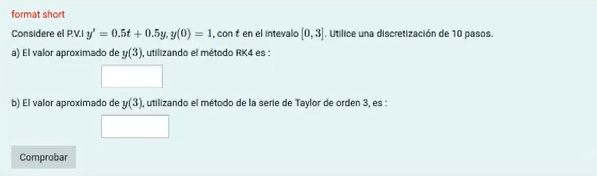

a=0; b=3;M=10; ya= 1;
f = @(t,y) 0.5*t+0.5*y;
H = heun (f, a, b, ya, M)

H =          0    1.0000
    0.3000    1.1854
    0.6000    1.4494
    0.9000    1.8047
    1.2000    2.2659
    1.5000    2.8504
    1.8000    3.5780
    2.1000    4.4718
    2.4000    5.5589
    2.7000    6.8703


La primer columna de H, Su ultima fila vemos y(3)=8.4426

syms t y
f1 = 0.5*t+0.5*y

$$f1 = \frac{t}{2}+\frac{y}{2}$$

T = taylorN(f1,3, a, b, ya, M) 

T =          0    1.0000
    0.3000    1.1854
    0.6000    1.4494
    0.9000    1.8047
    1.2000    2.2659
    1.5000    2.8504
    1.8000    3.5780
    2.1000    4.4718
    2.4000    5.5589
    2.7000    6.8703


Nuevamente, nos fijamos en la ultima fila y tenemos la aproximacion que es 8.4426 MELISIMO

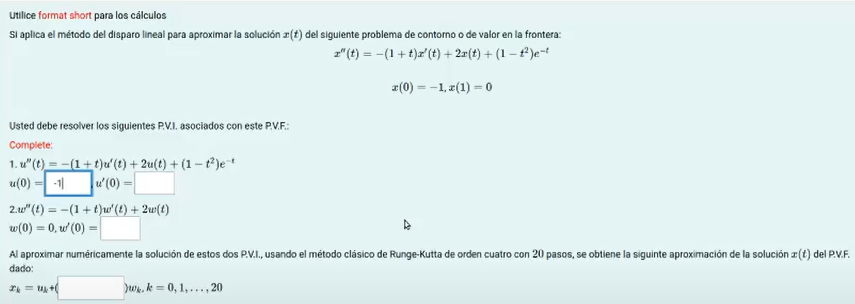

Empecemos notando que U(0) = -1 ya que U1= y(t) pero y(0)=-1 

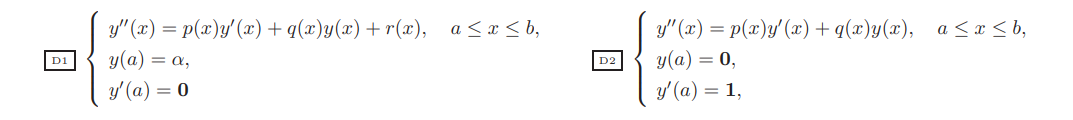

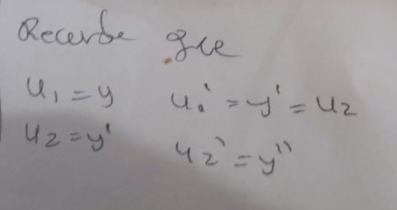

Tenemos en este caso que D1 en sus condiciones iniciales va a ser :

u(0) = -1 pues en D1 y(a)=alpha

u'(a)= ***0 cero *** por teoria de D1

w(0) = 0 ; ademas  w'(0)=1 pues este es el tramo de D2 y allí; se condiciona a 0,1

  este valor pedido corresponde a  

a = 0; b= 1; M = 20; 
z1 = [-0.5 0]; z2 = [0 1] 

z2 =      0     1


F1 = @(t,u) [u(2) , -(1+t)*u(2)+2*u(1)+(1-t.^2).*exp(-t)];
[T1, Z1] = rks4 (F1, a, b, z1, M)

T1 =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000


Z1 =    -0.5000         0
   -0.5000   -0.0012
   -0.5002   -0.0050
   -0.5006   -0.0111
   -0.5013   -0.0196
   -0.5026   -0.0304
   -0.5044   -0.0433
   -0.5069   -0.0582
   -0.5102   -0.0749
   -0.5144   -0.0934


u(b) = -0.6364

NOTA: Recuere que Z1 tiene las columnas U y U'

F2 = @(t,v) [v(2), -(1+t)*v(2)+2*v(1)];
[T2, Z2] = rks4 (F2, a, b, z2, M)

T2 =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000


Z2 =          0    1.0000
    0.0488    0.9525
    0.0953    0.9097
    0.1398    0.8714
    0.1825    0.8373
    0.2236    0.8073
    0.2633    0.7811
    0.3018    0.7584
    0.3392    0.7390
    0.3758    0.7227


v(b) = 0.7546

NOTA: Recuere que Z2 tiene las columnas V y V'

 tenemos a todos estos valores,donde beta es la condicion final y los otros los tenemos. calculemos:

coeficiente = (0-(-0.6364))/(0.7546) % Este es el valor pedido MELO

coeficiente = 0.8434